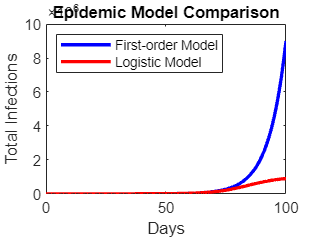

%%%%%%%%% 4
% Define the parameters
R0 = 1.15;
K = 1e6;
n = 100;

% Initialize arrays to store results
y = zeros(n+1, 1);
x = zeros(n+1, 1);

% Initial condition
y(1) = 1;

% Calculate y[n] for the first-order model
for i = 2:n+1
    y(i) = 1 + R0 * y(i - 1);
end

% Calculate x[n] for the logistic model
for i = 1:n+1
    x(i) = K / (1 + (K * (R0 - 1) - R0) * R0^(-i));
end

% Plot the results
figure;
plot(0:n, y, 'b', 'LineWidth', 2, 'DisplayName', 'First-order Model');
hold on;
plot(0:n, x, 'r', 'LineWidth', 2, 'DisplayName', 'Logistic Model');
xlabel('Days');
ylabel('Total Infections');
title('Epidemic Model Comparison');
legend('Location', 'Northwest');


% Part(1)
Ro = 1.15;
K = 10^6;
n = 1:101;

logistic = (K./(1+(K*(Ro-1) - Ro)*Ro.^(-n-1))) - (1/(Ro-1));
Integrator3 = filter(1,[1 -1],logistic);
Total_infections2 = Integrator3(end) % Total infections in 100 days

Total_infections2 = 1.7840e+07


% Part(2)
filter_1 = filter([1 -1],1,logistic); % First derivative
filter_2 = filter([1 -2 1],1,logistic); % Second derivative 

Global_maximum = max(filter_1) % Global max value

Global_maximum = 3.4918e+04

Value_n = n(filter_1 == max(filter_1)) % Days corresponding to max value

Value_n = 85

Zero_crossing = n(round(filter_2) == 94) % Inflection point

Zero_crossing = 85

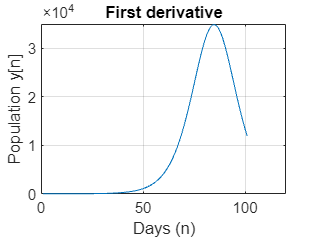


figure;
plot(n,filter_1)
title("First derivative")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on

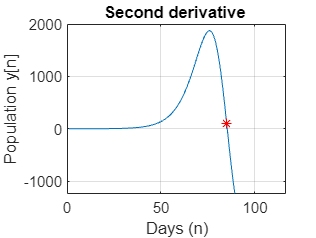


figure;
plot(n,filter_2,n(Zero_crossing),filter_2(Zero_crossing),'r*')
title("Second derivative ")
xlabel("Days (n)")
ylabel("Population y[n]")
grid on